Caso de estudio de filtros adaptativos

Generación de señal de prueba

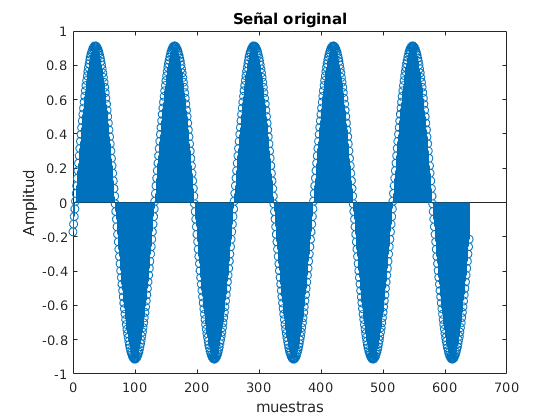

n=0:639;
f=1/128;
Ar1=sin(2*pi*f*n);
Ar2=cos((2*pi*f*n)-(pi/3));
Ar3=sin((2*pi*f*n)-(pi/4));
xn=Ar1-0.2*Ar2+0.1*Ar3;
figure()
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')
title('Señal original')

Observe que los tres armónicos son indistingubles en el dominio de la frecuencia (Se ve uno solo)

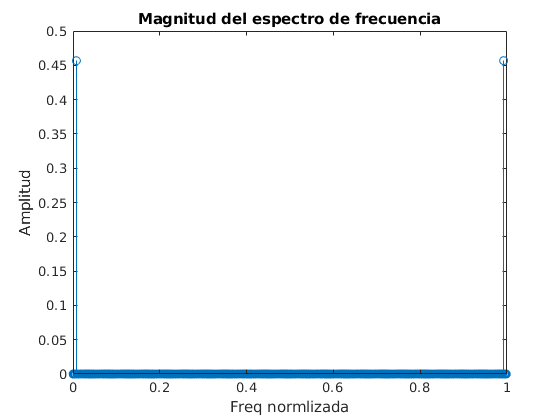

Xk=fft(xn)/length(n);
figure()
stem(n/length(n),abs(Xk))
xlabel('Freq normlizada')
ylabel('Amplitud')
title('Magnitud del espectro de frecuencia')

Aplique métodos de filtrado convencional para separar los armónicos

% Usando filtros convencionales

Aplique filtros adaptativos para separar los armónicos

% Usando filtros adaptativos